# **การทำนาย “ความคุ้มค่าราคากล้อง” ด้วย Linear & Multiple Regression (MATLAB)**

**การทำนาย “ความคุ้มค่าราคากล้อง” ด้วย Linear & Multiple Regression (MATLAB)**

***วัตถุประสงค์ (Objectives)***

- โหลดและตรวจสอบชุดข้อมูลกล้องจากไฟล์ `camera_dataset.csv`

- สร้างนิยาม **ตัวแปรเป้าหมาย: ความคุ้มค่าราคา (ValueForMoney)** เช่น

- ตัวอย่างสูตรเบื้องต้น: `ValueForMoney = Price / (Effective pixels + 1)`

- หรือดัชนีที่กลุ่มออกแบบเองจากหลายปัจจัย

- สร้างแบบจำลอง **Linear Regression (ตัวแปรทำนาย 1 ตัว)** เพื่ออธิบายความสัมพันธ์พื้นฐา

- ขยายเป็น **Multiple Linear Regression (หลายตัวแปร)** เพื่อเพิ่มความแม่นยำ

- ประเมินโมเดลด้วยตัวชี้วัดสำคัญ: **R², RMSE/MAE, p-value** และวิเคราะห์นัยสำคัญของตัวแปร

- ทำนาย “ความคุ้มค่า” ของ **กล้องตัวอย่าง** จากสเปคที่กำหนด และอภิปรายการใช้งาน/ข้อจำกัดของโมเดล

- เป้าหมายคือการสร้างโมเดลทำนายและประเมินความคุ้มค่าของกล้อง เพื่อดูว่าปัจจัยใดมีอิทธิพลต่อความคุ้มค่ามากที่สุด    

% การโหลดข้อมูล
fprintf('--- กำลังโหลดข้อมูล ---\n');

--- กำลังโหลดข้อมูล ---


try
    % ใช้ readtable เพื่อโหลดไฟล์ CSV
   T = readtable('camera_dataset.csv', 'TextType', 'string', ...
              'VariableNamingRule', 'preserve');
    fprintf('โหลดไฟล์ camera_dataset.csv สำเร็จ\n');
catch ME
    fprintf('!!! ข้อผิดพลาดในการโหลดไฟล์: %s\n', ME.message);
    fprintf('โปรดตรวจสอบว่าไฟล์ "camera_dataset.csv" อยู่ใน Path ปัจจุบันของ MATLAB\n');
    return; % หยุดการทำงาน
end

โหลดไฟล์ camera_dataset.csv สำเร็จ


%  ตรวจสอบข้อมูลเบื้องต้น
fprintf('--- กำลังตรวจสอบข้อมูลเบื้องต้น ---\n');

--- กำลังตรวจสอบข้อมูลเบื้องต้น ---


head(T)   % แสดงข้อมูลตัวอย่าง 6 แถวแรก

             Model              Release date    Max resolution    Low resolution    Effective pixels    Zoom wide (W)    Zoom tele (T)    Normal focus range    Macro focus range    Storage included    Weight (inc. batteries)    Dimensions    Price
    ________________________    ____________    ______________    ______________    ________________    _____________    _____________    __________________    _________________    ________________    _______________________    __________    _____

    "Agfa ePhoto 1280"              1997             1024    

size(T)   % แสดงขนาดตาราง (จำนวนแถว x คอลัมน์)

ans =         1038          13


sum(ismissing(T)) % ตรวจสอบว่ามีคอลัมน์/แถวที่เป็น ว่าง กี่ค่า

ans =      0     0     0     0     0     0     0     0     1     2     2     2     0


# **การคัดเลือกข้อมูล **

*เราจะเริ่มจากชุดตัวแปรขนาดเล็กที่อธิบายและทำกราฟได้ง่าย*

- **Effective pixels >** ความละเอียดของกล้อง (ล้านพิกเซล)

- **Max resolution >** ความละเอียดภาพสูงสุด

- **Release date >** ปีที่วางจำหน่าย

- **Weight (inc. batteries) >** น้ำหนักรวมแบตเตอรี่

- **Price >** ราคากล้อง

- **ValueForMoney (เป้าหมาย) >** ตัวชี้วัด “**ความคุ้มค่าราคา**” ที่เราสร้างขึ้นเอง

- *ตัวอย่างสูตรเริ่มต้น: *`ความคุ้มค่าราคา (ValueForMoney) = ราคา (Price) ÷ (ความละเอียดของกล้อง + 1)`

# **สร้างตารางทำงาน (Working Table)**

% เลือกตัวแปรที่ต้องใช้และสร้างตัวแปรเป้าหมาย (ความคุ้มค่า)
% สมมติ T ถูกอ่านไว้แล้วด้วย readtable('camera_dataset.csv')

% สร้างตัวแปรเป้าหมาย: ความคุ้มค่าราคา (ปรับสูตรได้)
T.ValueForMoney = T.Price ./ (T.("Max resolution") + 1); % +1 กันหารศูนย์
% เลือกคอลัมน์ที่ต้องใช้ทำโมเดล
T = T(:, {'Effective pixels', 'Max resolution', 'Release date', ...
             'Weight (inc. batteries)', 'Price', 'ValueForMoney'});
% จัดการค่าว่าง (ถ้ามี) – เอาแถวที่มีค่าว่างออกแบบง่าย ๆ
data = rmmissing(T);
% ดูสรุปเบื้องต้น
summary(T)


T: 1038×6 table

Variables:

    Effective pixels: double
    Max resolution: double
    Release date: double
    Weight (inc. batteries): double
    Price: double
    ValueForMoney: double

Statistics for applicable variables:

                             NumMissing       Min          Median        Max            Mean             Std     

    EffectivePixels              0                0             4          21            4.5963          2.8440  
    MaxResolution                0                0          2560        5616        2.4747e+03        759.5136  
    ReleaseDate                  0             1994          2004        2007        2.0036e+03          2.7248  
    Weight_inc_Batteries_

head(T)

    Effective pixels    Max resolution    Release date    Weight (inc. batteries)    Price    ValueForMoney
    ________________    ______________    ____________    _______________________    _____    _____________

           0                 1024             1997                  420               179        0.17463   
           1                 1280             1998                  420               179        0.13973   
           0                  640             2000                    0               179        0.27925   
           0                 1152             1999                    0               269         0.2333   
           0                 1152             1999                  300              1299         1.1266   
           1                 1600      

# **Linear Regression (Linear Regression – ตัวแปรอิสระ 1 ตัว)**

ในขั้นแรก เราจะสร้างโมเดลเพื่อทำนาย **ความคุ้มค่า (ValueForMoney)** โดยใช้เพียง **ความละเอียดของกล้อง (Effective pixels)** เป็นตัวอธิบายเดียว

เครื่องมือที่ใช้:

- `fitlm` (จาก Statistics and Machine Learning Toolbox)ใช้เพื่อ

- สร้างโมเดล Linear Regression

- ดูค่าสัมประสิทธิ์ (coefficients), ค่า R² และค่า p-value

- วาดกราฟเส้น regression และค่าความคลาดเคลื่อน (residuals)

**Linear Regression: ValueForMoney ~ EffectivePixels**

*เป้าหมายคือ* “**ความคุ้มค่า**”

X1 = T.("Max resolution");   % ตัวแปรอิสระ (ความละเอียดของกล้อง)
Y = T.ValueForMoney;           % ตัวแปรตาม (สิ่งที่เราจะทำนายคือ ความคุ้มค่าของราคา)

% สร้างโมเดลLinear Regression
linModel = fitlm(X1, Y);  

%  การประเมินผลแบบจำลอง
fprintf('--- ผลลัพธ์และการประเมินแบบจำลอง ---\n');

--- ผลลัพธ์และการประเมินแบบจำลอง ---


% แสดงรายละเอียดของแบบจำลอง
disp(linModel);


Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                    Estimate          SE         tStat       pValue  
                   ___________    __________    _______    __________

    (Intercept)         1.7916       0.42184      4.247    2.3615e-05
    x1             -0.00059347    0.00016297    -3.6416    0.00028431


Number of observations: 1038, Error degrees of freedom: 1036
Root Mean Squared Error: 3.99
R-squared: 0.0126,  Adjusted R-Squared: 0.0117
F-statistic vs. constant model: 13.3, p-value = 0.000284


% ดึงค่าตัวชี้วัดที่สำคัญ
R2_lin  = linModel.Rsquared.Ordinary;
coef    = linModel.Coefficients.Estimate;     % [ค่าคงที่; ความชัน]
pvals   = linModel.Coefficients.pValue;

% แสดงผลลัพธ์
fprintf('\n[Linear Regression] ค่า R^2 = %.3f\n', R2_lin);


[Linear Regression] ค่า R^2 = 0.013


fprintf('[Linear Regression] สมการ: ความคุ้มค่าราคา = %.2f + %.2f × ความละเอียดของกล้อง\n', coef(1), coef(2));

[Linear Regression] สมการ: ความคุ้มค่าราคา = 1.79 + -0.00 × ความละเอียดของกล้อง


fprintf('[Linear Regression] ค่า p-value: ค่าคงที่ = %.3g, ความชัน = %.3g\n\n', pvals(1), pvals(2));

[Linear Regression] ค่า p-value: ค่าคงที่ = 2.36e-05, ความชัน = 0.000284



%  การสร้างแบบจำลอง Linear Regression
fprintf('--- กำลังสร้างแบบจำลอง Regression ---\n');

--- กำลังสร้างแบบจำลอง Regression ---


% วาดกราฟ
figure('Name','Linear Regression: ความละเอียดกับความคุ้มค่า');
plot(linModel);
title('Linear Regression:  ความละเอียดของกล้อง vs ความคุ้มค่าราคา  ');
xlabel('ความละเอียดของกล้อง (ล้านพิกเซล)');
ylabel('ความคุ้มค่าราคา (ValueForMoney)');
%  การประเมินผลแบบจำลอง
fprintf('--- ผลลัพธ์และการประเมินแบบจำลอง ---\n');

--- ผลลัพธ์และการประเมินแบบจำลอง ---


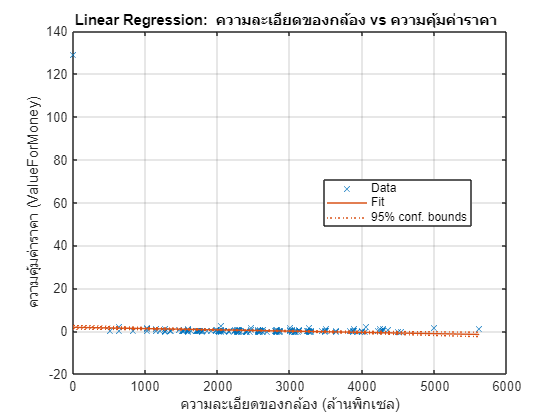

grid on;

fprintf('\n--- สิ้นสุดการวิเคราะห์ Regression ---\n');


--- สิ้นสุดการวิเคราะห์ Regression ---


**การตีความผลลัพธ์ (สิ่งที่ควรกล่าวถึง)**

- **เครื่องหมายของความชัน (Slope)**:ถ้าความชันเป็นบวก → ความละเอียดของกล้องริงมากขึ้น → ความคุ้มค่าราคากล้องสูงขึ้น (โดยเฉลี่ย)

- **ค่า R²**:ค่า R² ที่ใกล้ 1 แสดงว่า “จำนวนพิกเซล” สามารถอธิบายความคุ้มค่าของกล้องได้ดี

- **ค่า p-value**:ถ้า p-value < 0.05 หมายความว่า “ความละเอียดของกล้อง” มีผลต่อความคุ้มค่าของราคากล้องอย่างมีนัยสำคัญทางสถิติ

# **Multiple Linear Regression (เพิ่มตัวแปร)**

ตอนนี้เราจะเพิ่ม **ปีที่วางจำหน่าย** และ **น้ำหนักของกล้อง** เข้ามาในโมเดล    เพื่อเปรียบเทียบกับโมเดลแบบตัวแปรเดียว และดูว่า **ค่า R²** และสัมประสิทธิ์ต่าง ๆ ดีขึ้นหรือไม่

- **ความละเอียดสูงสุดของกล้อง (EffectivePixels หรือ MaxResolution)**

- **ปีที่วางจำหน่าย (ReleaseDate)**

- **น้ำหนักของกล้อง (Weight)**

**Multiple Linear Regression :** **ความคุ้มค่าราคา ~ ความละเอียด + ปีผลิต + น้ำหนัก**

%% Multiple Linear Regression (หลายตัวแปรอิสระ)
fprintf('---  Multiple Linear Regression : ใช้หลายตัวแปร ---\n');

---  Multiple Linear Regression : ใช้หลายตัวแปร ---


% เลือกตัวแปรอิสระหลายตัว
Xtable = T(:, {'Max resolution', 'Weight (inc. batteries)', 'Release date'});
Y = T.ValueForMoney;

% สร้างโมเดล Multiple Linear Regression
multiModel = fitlm(Xtable, Y);
%  การประเมินผลแบบจำลอง
fprintf('--- ผลลัพธ์และการประเมินแบบจำลอง ---\n');

--- ผลลัพธ์และการประเมินแบบจำลอง ---


disp(multiModel);


Linear regression model:
    y ~ 1 + Max resolution + Weight (inc. batteries) + Release date

Estimated Coefficients:
                                Estimate         SE         tStat       pValue  
                               __________    __________    _______    __________

    (Intercept)                   -937.14        176.33    -5.3146    1.3093e-07
    Max resolution             -0.0019991    0.00030759    -6.4992    1.2547e-10
    Weight (inc. batteries)     0.0020741    0.00057159     3.6288    0.00029874
    Release date                  0.47003       0.08828     5.3244     1.243e-07


Number of observations: 1036, Error degrees of freedom: 1032
Root Mean Squared Error: 3.94
R-squared: 0.0396,  Adjusted R-Squared: 0.0368
F-statistic vs. constant model: 14.2, p-value = 4.

% ดึงค่า R^2
R2_multi = multiModel.Rsquared.Ordinary;

% สมมติว่าคุณคำนวณ R^2 ของโมเดลตัวแปรเดียวไว้แล้วในตัวแปร R2_lin
fprintf('\n[Multiple] ค่า R^2 = %.3f (เมื่อเปรียบเทียบกับโมเดลตัวแปรเดียว R^2 = %.3f)\n', R2_multi, R2_lin);


[Multiple] ค่า R^2 = 0.040 (เมื่อเปรียบเทียบกับโมเดลตัวแปรเดียว R^2 = 0.013)


%  การสร้างแบบจำลอง Multiple Linear Regression
fprintf('--- กำลังสร้างแบบจำลอง Regression ---\n');

--- กำลังสร้างแบบจำลอง Regression ---


% แสดงกราฟ bar ของความสำคัญตัวแปร
% กราฟแสดงความสำคัญของตัวแปรอิสระด้วยค่า |t-stat|
% ---------------------------------------------------
% ขั้นตอนนี้เราจะดูว่าตัวแปรอิสระ (predictors) แต่ละตัวมีความสำคัญ
% ต่อโมเดล Multiple Regression แค่ไหน
% โดยใช้ค่า t-statistic จากผลลัพธ์ Multiple 
% - ยิ่งค่า |t-stat| มีค่าสูง แสดงว่าตัวแปรนั้นมีอิทธิพลต่อการอธิบาย ความคุ้มค่าราคามาก
% - ถ้าค่า |t-stat| ต่ำ แสดงว่าตัวแปรนั้นอาจไม่มีผลสำคัญทางสถิติ

coefTbl = multiModel.Coefficients;                                % ตารางสัมประสิทธิ์ของโมเดล
isPredictor = ~strcmp(coefTbl.Properties.RowNames,'(Intercept)'); % ตัด intercept ออก
tstats = abs(coefTbl.tStat(isPredictor));                         % ค่า |t-stat|
labels = coefTbl.Properties.RowNames(isPredictor);                % ชื่อของตัวแปรอิสระ

% วาดกราฟแท่ง
figure('Name','ความสำคัญของตัวแปรอิสระ (|t-stat|)');
bar(tstats) ;
set(gca,'XTickLabel',labels,'XTickLabelRotation',30);              % ป้ายชื่อแกน X หมุน 30 องศา
ylabel('|t-statistic|');
xlabel('ตัวแปรอิสระ');
title('ความสำคัญเชิงเปรียบเทียบของตัวแปรอิสระ');
%  การประเมินผลแบบจำลอง
fprintf('--- ผลลัพธ์และการประเมินแบบจำลอง ---\n');

--- ผลลัพธ์และการประเมินแบบจำลอง ---


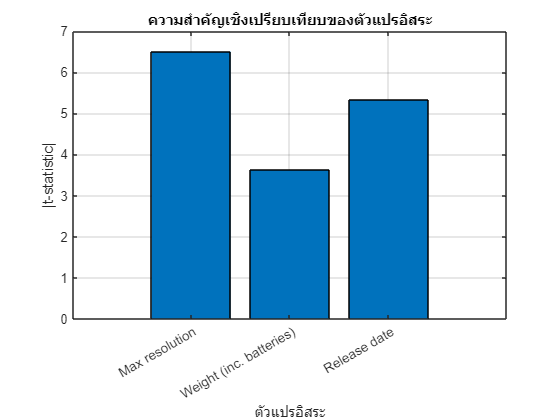

grid on;

fprintf('\n--- สิ้นสุดการวิเคราะห์ Regression ---\n');


--- สิ้นสุดการวิเคราะห์ Regression ---


# **Prediction for a New Camera (การทำนายราคากล้องใหม่)**

ลองทำนาย “ความคุ้มค่าราคา” ของกล้องสมมติ 1 ตัว ที่มีสเปกดังนี้:

- ความละเอียดสูงสุดของภาพ = 4096

- ปีที่วางจำหน่าย = 2025

- น้ำหนัก = 650 กรัม

**ทำการทำนาย**

%% Prediction for a New Camera (การทำนายสำหรับกล้องใหม่)
% ตัวอย่าง: กล้องสมมติที่มีคุณสมบัติ 3 อย่าง
% - ความละเอียดสูงสุุดของภาพ = 4096  
% - ปีที่วางจำหน่าย = 2025
% - น้ำหนัก = 650 กรัม

newCamera = table(4096, 2025, 650, ...
    'VariableNames', {'Max resolution','Release date','Weight (inc. batteries)'});

% ใช้โมเดล multiple regression ที่สร้างไว้ทำนาย
predValue = predict(multiModel, newCamera);
fprintf('ค่าความคุ้มค่าที่ทำนายได้สำหรับกล้อง [ความละเอียดสูงสุดของภาพ=4096 , ปี=2025, น้ำหนัก=650 กรัม] = $%.2f\n', predValue);

ค่าความคุ้มค่าที่ทำนายได้สำหรับกล้อง [ความละเอียดสูงสุดของภาพ=4096 , ปี=2025, น้ำหนัก=650 กรัม] = $7.83


# **Mini Exercise **

ทำนายความคุ้มค่าราคาของกล้องสมมติ 2–3 รุ่น แล้วเปรียบเทียบความแตกต่างกัน

%% สร้างกล้องสมมติ 3 รุ่น
newCameras = table(...
    [4096 ; 4096 ; 2560 ], ...       % ความละเอียดสูงสุดของกล้อง
    [2025; 2015; 2022], ...       % ปีที่วางจำหน่าย
    [262; 450; 600], ...          % น้ำหนักของกล้อง (กรัม)
   'VariableNames', {'Max resolution','Release date','Weight (inc. batteries)'});

% ทำนายความคุ้มค่าราคา
predictedValues = predict(multiModel, newCameras);

% รวมผลลัพธ์
results = [newCameras table(predictedValues)];
disp(results)

    Max resolution    Release date    Weight (inc. batteries)    predictedValues
    ______________    ____________    _______________________    _______________

         4096             2025                  262                   7.026     
         4096             2015                  450                  2.7157     
         2560             2022                  600                  9.3876     



# **Question**

- ถ้ากล้องมีความละเอียดสูง (พิกเซลเยอะ) แต่ราคาแพงมาก โมเดลจะทำนายความคุ้มค่าออกมาเป็นอย่างไร?

- ระหว่าง “ความละเอียดของกล้อง” และ “ปีที่วางจำหน่าย” ตัวแปรใดมีผลต่อความคุ้มค่ามากกว่า?

- คุณคิดว่าโมเดลนี้สะท้อนพฤติกรรมการเลือกซื้อกล้องจริง ๆ ของผู้ใช้ได้หรือไม่? เพราะอะไร?้

# ** สรุปบทเรียน **

- **Linear Regression (ตัวแปรเดียว)** ช่วยอธิบายความสัมพันธ์พื้นฐานระหว่างตัวแปรอิสระเพียงตัวเดียว (เช่น ความละเอียดของกล้อง) กับตัวแปรตาม (Value for Money)

- **Multiple Linear Regression** ใช้หลาย predictors (เช่น ความละเอียด, ปีที่วางจำหน่าย, น้ำหนัก) เพื่อให้การทำนายแม่นยำขึ้น

- **Key outputs** ที่ควรรายงาน ได้แก่ **Equation**, ค่า **R²**, ค่า **p-value** และ **Prediction examples**

- กระบวนการนี้สามารถประยุกต์ใช้กับงานจริงได้หลายด้าน เช่น **pricing, sales, energy analysis** เป็นต้น